cochleagramLength = 22;
filtBanks.fs44100 = gammatoneFilterBank([50 20000],64,44100);
filtBanks.fs48000 = gammatoneFilterBank([50 20000],64,48000);
filtBanks.fs32000 = gammatoneFilterBank([50 16000],64,32000);

## Blackbird vs Nightingale binary SVM MFCC classification

class1 = 'TURMER';
class2 = 'LUSMEG';

XTrain1 = buildFeatureMatrix(class1,cochleagramLength,filtBanks);
XTrain2 = buildFeatureMatrix(class2,cochleagramLength,filtBanks);

XTrain = [XTrain1;XTrain2];
YTrain = ones(size(XTrain,1),1);
YTrain(1:size(XTrain1,1)) = -1;

linearSVM = fitcsvm(XTrain,YTrain,'KernelFunction','linear', ...
    'Standardize',true,'ClassNames',[-1,1]);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.42663 |      101.71 |     0.42663 |     0.42663 |    0.0014467 |       32.368 |
|    2 | Best   |     0.20407 |      67.711 |     0.20407 |     0.21976 |       6.7977 |       340.19 |
|    3 | Accept |     0.42663 |      120.69 |     0.20407 |      0.2041 |    0.0060823 |     0.019185 |
|    4 | Accept |     0.42663 |      115.75 |     0.20407 |      0.2041 |       410.12 |    0.0052189 |
|    5 | Accept |     0.42663 |      113.03 |     0.20407 |      0.2041 |       2.4552 |    0.0030744 |
|    6 | Accept |     0.22558 |      70.083 |     0.20407 |     

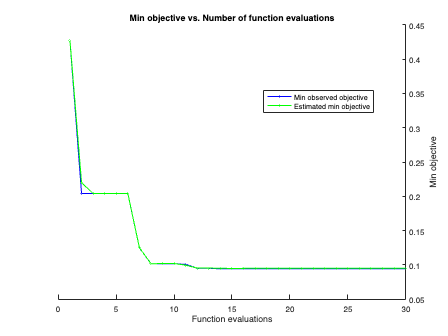

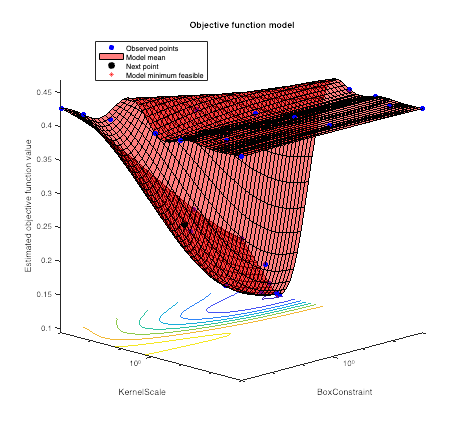


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 2533.7861 seconds
Total objective function evaluation time: 2495.9348

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

       995.24          60.157   

Observed objective function value = 0.094304
Estimated objective function value = 0.095095
Function evaluation time = 47.45

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       995.24          60.157   

Estimated objective function value = 0.095095
Estimated function evaluation time = 47.1776



rbfSVM =   ClassificationSVM
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [-1 1]
                       ScoreTransform: 'none'
                      NumObservations: 2651
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                                Alpha: [839×1 double]
                                 Bias: 0.3072
                     KernelParameters: [1×1 struct]
                       BoxConstraints: [2651×1 double]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [2651×1 logical]
                               Solver: 'SMO'


  Properties, Methods


c = cvpartition(size(XTrain,1),'KFold',5);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
rbfSVM = fitcsvm(XTrain,YTrain,'KernelFunction','rbf', ...
    'OptimizeHyperparameters','auto', 'ClassNames',[-1,1], ...
    'HyperparameterOptimizationOptions',opts)

### Testing performance on unseen blackbird call

[lCA, rbfCA] = testUnseen('samples/TURMER/test/XC789465.mp3',-1,linearSVM,rbfSVM,cochleagramLength,filtBanks);
fprintf('Linear classification accuracy: %.2f%%\n', lCA*100);

Linear classification accuracy: 13.27%


fprintf('RBF classification accuracy: %.2f%%\n', rbfCA*100);

RBF classification accuracy: 20.41%


### Testing performance on unseen nightingale call

[lCA, rbfCA] = testUnseen('samples/LUSMEG/test/XC810376.wav',1,linearSVM,rbfSVM,cochleagramLength,filtBanks);
fprintf('Linear classification accuracy: %.2f%%\n', lCA*100);

Linear classification accuracy: 4.44%


fprintf('RBF classification accuracy: %.2f%%\n', rbfCA*100);

RBF classification accuracy: 37.78%


# ----- Helper Functions -----

function [lCA, rbfCA] = testUnseen(sample,class,linearSvm,rbfSmv,cochleagramLength,filtBanks)
[audio,fs] = audioread(sample);
audio = mono(audio);
audio = stripSound(audio,fs);
gt = filtBanks.(sprintf('fs%d',fs));
syllables = segmentSyllables(audio,fs);
predsLinear = zeros(3,numel(syllables));
predsRbf = zeros(3,numel(syllables));
for ii = 1:numel(syllables)
    mrcgTest = extractMrcgFeature(gt,syllables{ii},fs,cochleagramLength);
    [labelLinear,scoreLinear] = predict(linearSvm,mrcgTest);
    predsLinear(:,ii) = [labelLinear,scoreLinear];
    [labelRbf,scoreRbf] = predict(rbfSmv,mrcgTest);
    predsRbf(:,ii) = [labelRbf,scoreRbf];
end
lCA = sum(predsLinear(1,:)==class)/numel(syllables);
rbfCA = sum(predsRbf(1,:)==class)/numel(syllables);
end

function featureMatrix = buildFeatureMatrix(birdID,cochleagramLength,filtBanks)
directoryPath = sprintf('samples/%s/syllables',birdID);
fileList = dir(fullfile(directoryPath, '*.wav'));
featureMatrix = zeros(numel(fileList),cochleagramLength*256);
for ii = 1:numel(fileList)
    filePath = fullfile(directoryPath, fileList(ii).name);
    [signal, fs] = audioread(filePath);
    gt = filtBanks.(sprintf('fs%d',fs));
    featureMatrix(ii,:) = extractMrcgFeature(gt,signal,fs,cochleagramLength);
end
end